# Demo 5: ocena wyników (evaluateDetections)

Zbiór ma tylko ramki, a nie maski, więc segmentację oceniamy pośrednio: każdy wysegmentowany obiekt zamieniamy na ramkę i dopasowujemy do ramek wzorcowych. Skrypt pokazuje miarę IoU, dopasowanie zachłanne, liczenie TP/FP/FN oraz wpływ progu IoU na wynik.

## Konfiguracja

W Live Editorze mfilename wskazuje na plik tymczasowy w /tmp, dlatego sprawdzamy kilka możliwych lokalizacji skryptu i wybieramy tę, dla której istnieje folder data/ dwa poziomy wyżej.

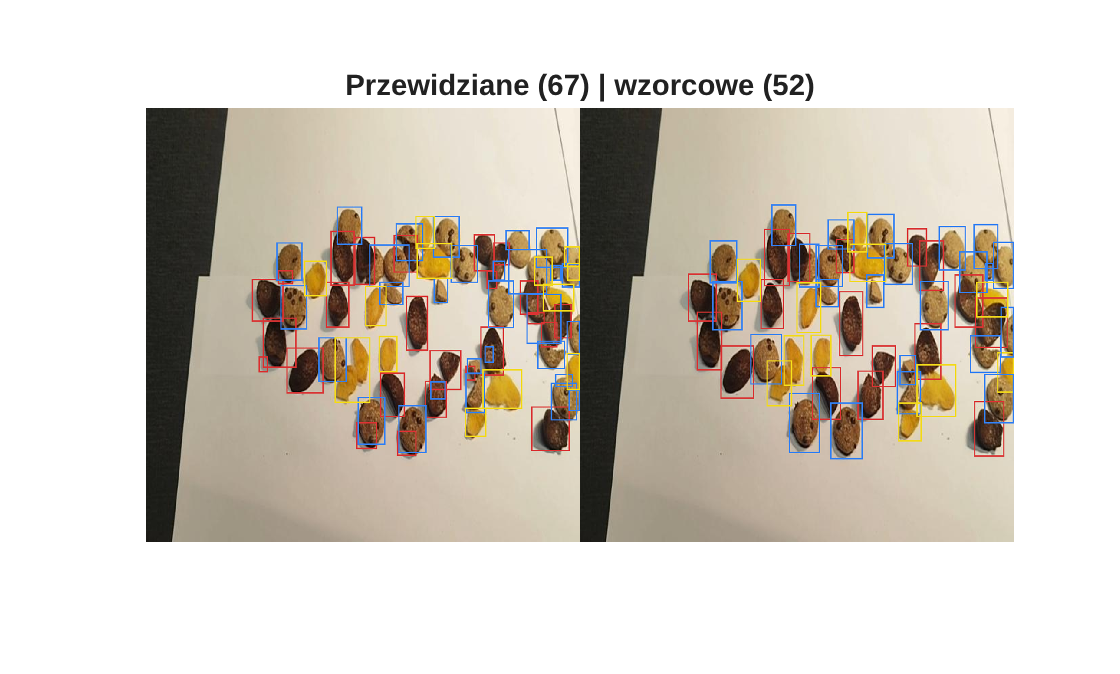

candidates = string(fileparts(mfilename("fullpath")));
try
    candidates(end+1) = fileparts(matlab.desktop.editor.getActiveFilename);
catch
end
candidates(end+1) = pwd;
candidates = candidates(candidates ~= "");
ok = arrayfun(@(d) isfolder(fullfile(d, "..", "..", "data")), candidates);
assert(any(ok), "Nie znaleziono folderu data/. Ustaw Current Folder na segmentation/demo.")
demoDir = candidates(find(ok, 1));
segDir  = fileparts(demoDir);
addpath(segDir);
dataDir = fullfile(segDir, "..", "data", "Mlekolaki.v3i.coco");

classNames = ["choco", "cookie", "corn"];
colors = [0.85 0.2 0.2; 0.2 0.5 0.95; 0.95 0.85 0.1];

lutFile = fullfile(segDir, "results", "colorLUT.mat");
if isfile(lutFile)
    load(lutFile, "lut");
else
    lut = trainPixelClassifier(loadCoco(fullfile(dataDir, "train")));
end

test = loadCoco(fullfile(dataDir, "test"));
i = find(contains([test.file], "Video2_mp4-218"), 1);
I = imread(test(i).file);
gtBox = test(i).boxes; gtLbl = test(i).labels;

[~, ~, inst] = segmentImage(I, lut);
predBox = reshape([inst.bbox], 4, []).';
predLbl = [inst.label].';

figure
montage({insertShape(I, "rectangle", predBox, "Color", colors(predLbl, :) * 255, "LineWidth", 2), ...
         insertShape(I, "rectangle", gtBox, "Color", colors(gtLbl, :) * 255, "LineWidth", 2)}, "Size", [1 2])
title(sprintf("Przewidziane (%d) | wzorcowe (%d)", numel(predLbl), numel(gtLbl)))

## Krok 1: miara IoU

IoU (Intersection over Union) = pole części wspólnej / pole sumy dwóch ramek. 1 oznacza idealne pokrycie, 0 brak części wspólnej. Przykład dla dwóch ramek przesuniętych o 10 px:

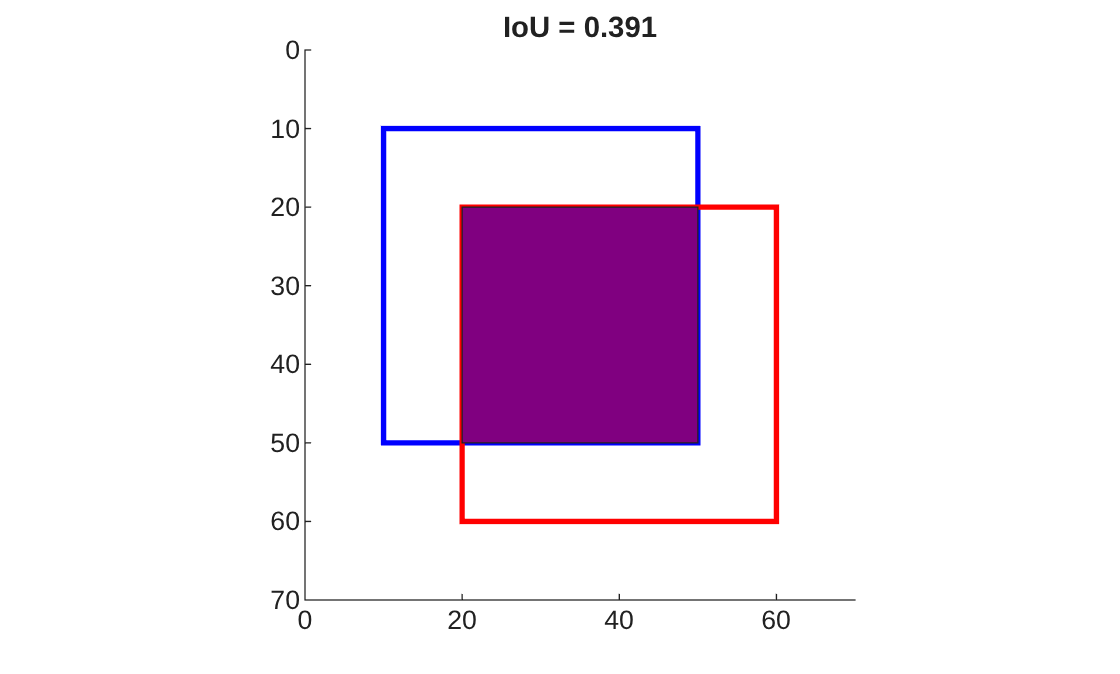

A = [10 10 40 40]; B = [20 20 40 40];
figure; hold on; axis ij equal; xlim([0 70]); ylim([0 70])
rectangle("Position", A, "EdgeColor", "b", "LineWidth", 2)
rectangle("Position", B, "EdgeColor", "r", "LineWidth", 2)
rectangle("Position", [20 20 30 30], "FaceColor", [0.5 0 0.5 0.3])
hold off
title(sprintf("IoU = %.3f", bboxOverlapRatio(A, B)))

## Krok 2: macierz IoU dla jednej klasy

Dla klasy cookie liczymy IoU każdej przewidzianej ramki z każdą ramką wzorcową. Większość par ma IoU = 0, bo ramki leżą daleko od siebie.

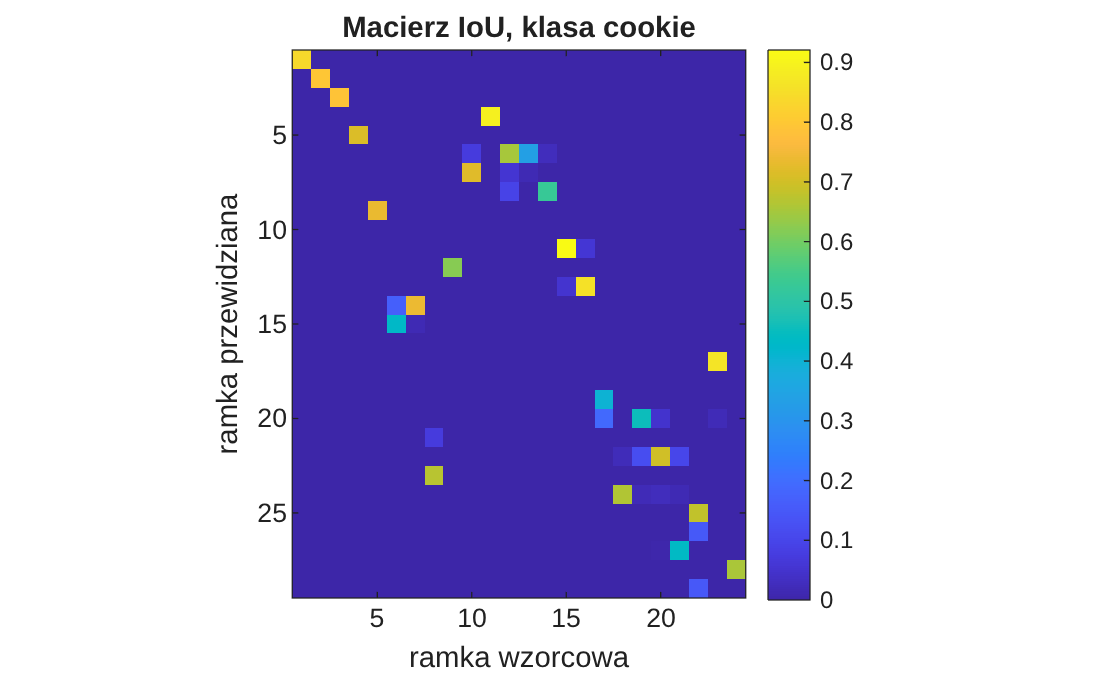

c = 2;
P = predBox(predLbl == c, :);
G = gtBox(gtLbl == c, :);
iou = bboxOverlapRatio(P, G);
figure; imagesc(iou); colorbar; axis image
xlabel("ramka wzorcowa"); ylabel("ramka przewidziana")
title("Macierz IoU, klasa " + classNames(c))

## Krok 3: dopasowanie zachłanne

Bierzemy parę o największym IoU, uznajemy ją za dopasowaną i usuwamy obie ramki z dalszego dopasowania. Powtarzamy, dopóki najlepsze IoU jest co najmniej równe progowi (0.5). Każda ramka może być dopasowana tylko raz.

thr = 0.5;
work = iou;
pairs = zeros(0, 3);
while ~isempty(work)
    [v, idx] = max(work(:));
    if v < thr, break; end
    [p, g] = ind2sub(size(work), idx);
    pairs(end+1, :) = [p g v]; %#ok<SAGROW>
    work(p, :) = 0; work(:, g) = 0;
end
array2table(pairs(1:min(10, end), :), 'VariableNames', ["przewidziana", "wzorcowa", "IoU"])

ans = 10×3 table
    przewidziana    wzorcowa      IoU  
    ____________    ________    _______

         11            15       0.92083
          4            11       0.89327
         17            23       0.86395
         13            16        0.8561
          1             1        0.8416
          2             2       0.79659
          3             3       0.78806
         14             7       0.74097
          9             5        0.7362
          7            10       0.72093


fprintf("Dopasowano %d z %d przewidzianych i %d wzorcowych ramek\n", size(pairs, 1), size(P, 1), size(G, 1));

Dopasowano 19 z 29 przewidzianych i 24 wzorcowych ramek


## Krok 4: TP, FP, FN na obrazie

TP (true positive): przewidziana ramka dopasowana do wzorcowej. FP (false positive): przewidziana ramka bez pary, czyli fałszywy obiekt. FN (false negative): wzorcowa ramka bez pary, czyli pominięty obiekt.

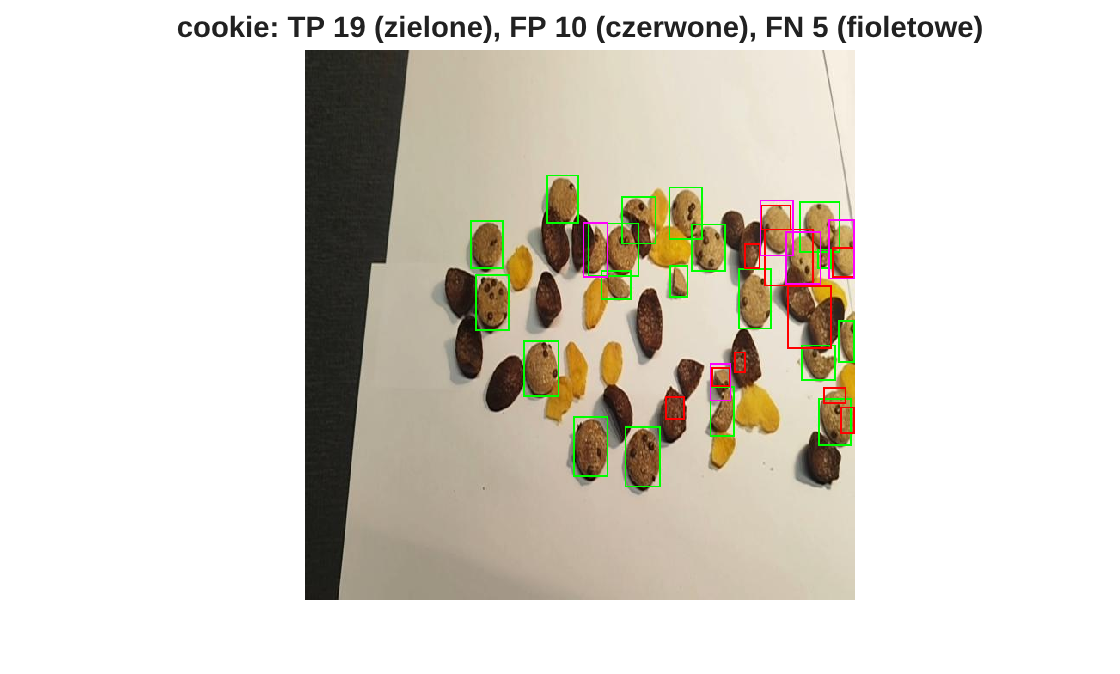

tpP = false(size(P, 1), 1); tpP(pairs(:, 1)) = true;
tpG = false(size(G, 1), 1); tpG(pairs(:, 2)) = true;
vis = insertShape(I, "rectangle", P(tpP, :), "Color", "green", "LineWidth", 2);
vis = insertShape(vis, "rectangle", P(~tpP, :), "Color", "red", "LineWidth", 2);
vis = insertShape(vis, "rectangle", G(~tpG, :), "Color", "magenta", "LineWidth", 2);
figure; imshow(vis)
title(sprintf("%s: TP %d (zielone), FP %d (czerwone), FN %d (fioletowe)", ...
    classNames(c), sum(tpP), sum(~tpP), sum(~tpG)))

## Krok 5: precyzja, czułość i F1

Precyzja = TP / (TP + FP): jaka część wykrytych obiektów jest prawdziwa. Czułość = TP / (TP + FN): jaka część prawdziwych obiektów została wykryta. F1 = średnia harmoniczna precyzji i czułości.

r = evaluateDetections(predBox, predLbl, gtBox, gtLbl, thr);
prec = r.tp ./ (r.tp + r.fp);
rec  = r.tp ./ (r.tp + r.fn);
f1   = 2 * prec .* rec ./ (prec + rec);
table(classNames.', r.tp.', r.fp.', r.fn.', prec.', rec.', f1.', ...
    'VariableNames', ["klasa", "TP", "FP", "FN", "precyzja", "czulosc", "F1"])

ans = 3×7 table
     klasa      TP    FP    FN    precyzja    czulosc      F1   
    ________    __    __    __    ________    _______    _______

    "choco"     14    11    3        0.56     0.82353    0.66667
    "cookie"    19    10    5     0.65517     0.79167    0.71698
    "corn"       9     4    2     0.69231     0.81818       0.75


fprintf("Zgodność z krokiem 3 (klasa %s): TP %d vs %d\n", classNames(c), r.tp(c), size(pairs, 1));

Zgodność z krokiem 3 (klasa cookie): TP 19 vs 19


## Krok 6: wpływ progu IoU

Niski próg akceptuje niedokładne ramki, wysoki wymaga prawie idealnego pokrycia. Ramki z segmentacji są zwykle trochę inne niż ramki ręczne, dlatego F1 szybko spada powyżej ok. 0.7.

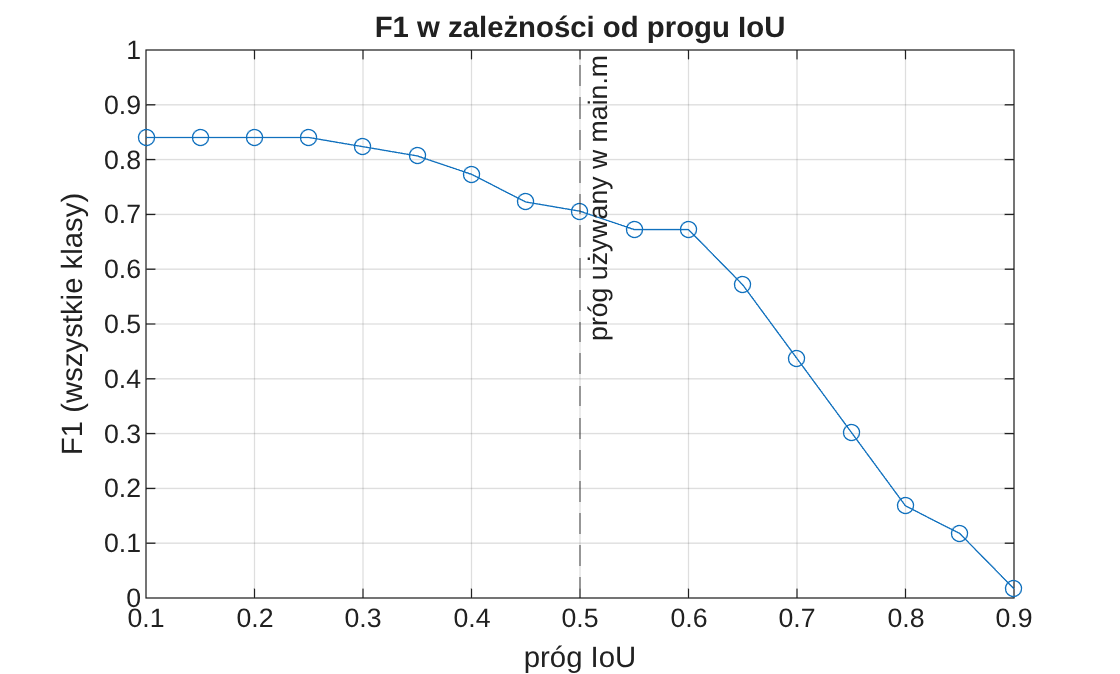

thrs = 0.1:0.05:0.9;
F1 = zeros(size(thrs));
for t = 1:numel(thrs)
    r = evaluateDetections(predBox, predLbl, gtBox, gtLbl, thrs(t));
    F1(t) = 2 * sum(r.tp) / (2 * sum(r.tp) + sum(r.fp) + sum(r.fn));
end
figure
plot(thrs, F1, "-o"); xline(0.5, "--", "próg używany w main.m")
xlabel("próg IoU"); ylabel("F1 (wszystkie klasy)"); ylim([0 1]); grid on
title("F1 w zależności od progu IoU")